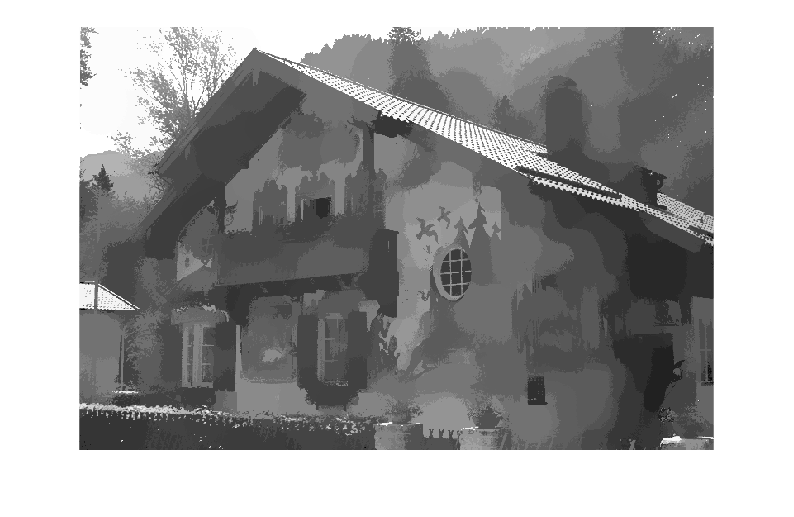

rng(10);
kodak = double(imread('kodak24.png'));
size(kodak);
barbara = double(imread('barbara256.png'));
noise1 = random('normal',0,5,size(kodak));
noise2 = random('normal', 0, 5, size(barbara));
noise3 = random('normal',0,10,size(kodak));
noise4 = random('normal', 0, 10, size(barbara));

kodak1 = kodak+noise1;
barbara1 = barbara + noise2;
kodak2 = kodak+noise3;
barbara2 = barbara + noise4;

a = [2,2;0.1,0.1;3,15];
imwrite(kodak1/255, "../images/kodak_5.png");
imwrite(kodak2/255, "../images/kodak_10.png");
imwrite(barbara1/255, "../images/barbara_5.png");
imwrite(barbara2/255, "../images/barbara_10.png");

for i=1:3
    k1 = meanshift(kodak1, a(i,1), a(i,2), 31, 5, 45, 100);
    imshow(k1/255);
    %imwrite(k1/255, "../images/kodak_5_"+i+".png");
end

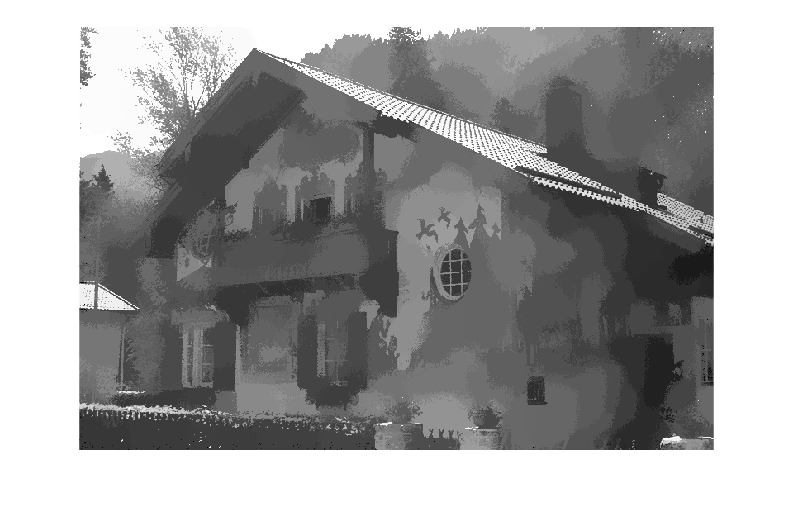

for i=1:3
    k1 = meanshift(kodak2, a(i,1), a(i,2), 31, 5, 45, 100);
    imshow(k1/255);
    %imwrite(k1/255, "../images/kodak_10_"+i+".png");
end

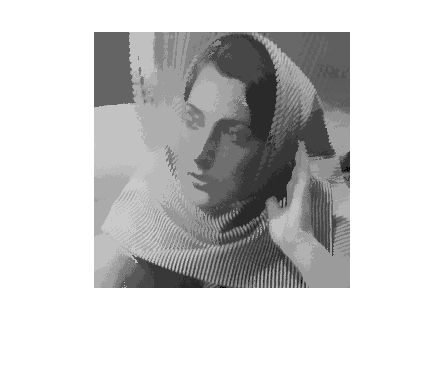

for i=1:3
    b1 = meanshift(barbara1, a(i,1), a(i,2), 31, 5, 45, 100);
    imshow(b1/255);
    %imwrite(b1/255, "../images/barbara_5_"+i+".png");
end

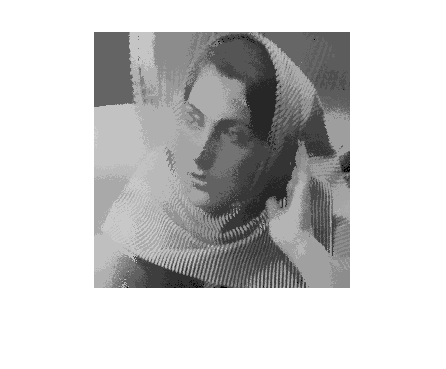

for i=1:3
    b1 = meanshift(barbara2, a(i,1), a(i,2), 31, 5, 45, 100);
    imshow(b1/255);
    %imwrite(b1/255, "../images/barbara_10_"+i+".png");
end